# Problema de Despacho Econômico para 40 Geradores

## Parâmetros do algoritmo

tic
n = 100; % Número de morcegos
MaxIterations = 2000; % Número máximo de iterações
A0 = 1; % Loudness inicial
r0 = 0.5; % Pulse rate inicial
alpha = 0.9; % Taxa de redução de loudness (valor recomendado pela literatura)
gamma = 0.9; % Taxa de aumento de pulse rate (valor recomendado pela literatura)
betta = -1 + 2*rand(1); % vetor aleatório pertence ao intervalo [0,1]
f_min = zeros(n, 1); % Frequência mínima
f_max = rand(n, 1);% Frequência máxima
% sigma = 0.1; % fator de escala
% f_max = transpose(linspace(1000*n, 1)); % Frequência máxima
% f_max = 100000.*rand(n,1);

## Parâmetros do Sistema de Geração Termelétrico

% Constantes
G = [1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20   21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40]; % 40 unidades de geração
Pmin_G = [36    36    60    80    47    68   110   135   135   130    94    94   125   125   125   125   220   220   242   242   254   254   254   254   254   254    10    10    10    47    60    60    60    90    90    90    25    25    25   242]; % Potência gerada mínima de cada unidade
Pmax_G = [114   114   120   190    97   140   300   300   300   300   375   375   500   500   500   500   500   500   550   550   550   550   550   550   550   550   150   150   150    97   190   190   190   200   200   200   110   110   110   550]; % Potência gerada máxima de cada unidade
PD = 10500; % Potência ativa demandada pelo sistema [MW]

% Parâmetros da função de custo de produção das unidades termelétricas
a = [0.00690    0.00690    0.02028    0.00942    0.01140    0.01142    0.00357    0.00492    0.00573    0.00605    0.00515    0.00569   0.00421    0.00752    0.00752    0.00752    0.00313    0.00313    0.00313    0.00313    0.00298    0.00298    0.00284    0.00284   0.00277    0.00277    0.52124    0.52124    0.52124    0.01140    0.00160    0.00160    0.00160    0.00010    0.00010    0.00010   0.01610    0.01610    0.01610    0.00313];
b = [6.7300    6.7300    7.0700    8.1800    5.3500    8.0500    8.0300    6.9900    6.6000   12.9000   12.9000   12.8000   12.5000    8.8400    8.8400    8.8400    7.9700    7.9500    7.9700    7.9700    6.6300    6.6300    6.6600    6.6600   7.1000    7.1000    3.3300    3.3300    3.3300    5.3500    6.4300    6.4300    6.4300    8.9500    8.6200    8.6200   5.8800    5.8800    5.8800    7.9700];
c = [94.705    94.705    309.540    369.030    148.890    222.330    287.710    391.980    455.760    722.820    635.200    654.690   913.400    1760.400    1760.400     1760.400    647.850    649.690    647.830    647.810    785.960    785.960    794.530    794.530    801.320   801.320    1055.100    1055.100    1055.100    148.890    222.920    222.920    222.920    107.870    116.580    116.580    307.450   307.450    307.450    647.830];
e = [100   100   100   150   120   100   200   200   200   200   200   200   300   300   300   300   300   300   300   300   300   300   300   300   300   300   120   120   120   120   150   150   150   200   200   200    80    80    80   300];
f = [0.0840    0.0840    0.0840    0.0630    0.0770    0.0840    0.0420    0.0420    0.0420    0.0420    0.0420    0.0420   0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350   0.0350    0.0350    0.0770    0.0770    0.0770    0.0770    0.0630    0.0630    0.0630    0.0420    0.0420    0.0420   0.0980    0.0980    0.0980    0.0350];

## Função objetivo

% Custo de produção da unidade de geração termelétrica
cost_function = @(PG) sum(a .* PG.^2 + b .* PG + c + abs(e .* sin(f .* (Pmin_G - PG))));

obj_fun = @(PG) cost_function(PG) + 1e6 * abs(sum(PG) - PD); % função objetivo com penalização

## Função inicialização da população de morcegos

% Inicialização da população de morcegos
d = length(G); % Dimensão do problema
LB = Pmin_G; % Limite inferior
UB = Pmax_G; % Limite superior
x = LB + (UB - LB) .* rand(n, d); % Posições iniciais
v = zeros(n, d); % Velocidades iniciais
freq = zeros(n, 1); % Frequências iniciais
pulse_rate = r0 * ones(n, 1); % Pulse rates
loudness = A0 * ones(n, 1); % Loudness
fitness = zeros(n, 1);

## Função principal

% Avaliar a população inicial
for i = 1:n
    fitness(i) = obj_fun(x(i, :));
end

% Encontrar a melhor solução inicial
[best_fitness, best_idx] = min(fitness);
x_best = x(best_idx, :);


% Loop principal do algoritmo
t = 1;
while t <= MaxIterations
    for i = 1:n
        % Atualizar frequência
        freq(i) = f_min(i, :) + (f_max(i, :) - f_min(i, :)).*betta;

        % Atualizar velocidade
        v(i, :) = v(i, :) + (x(i, :) - x_best) * freq(i);

        % Atualizar posição
        x(i, :) = x(i, :) + v(i, :);

        % Limitar posição aos limites inferiores e superiores
        x(i, :) = max(LB, min(UB, x(i, :)));

        % Selecionar uma solução entre as melhores soluções
        if rand > pulse_rate(i)
            epsilon = randn(size(x_best)); % vetor aleatório extraído de uma distribuição  normal Gaussiana N(0,1)
            x_new = x_best + epsilon .* mean(loudness);
        else
            x_new = LB + (UB - LB) .* rand(1, d);
        end

        % Limitar nova posição aos limites inferiores e superiores
        x_new = max(LB, min(UB, x_new));

        % Ajustar x_new para atender à restrição de igualdade (sum(PG) = PD)
        sum_x_new = sum(x_new);
        if sum_x_new ~= PD
            x_new = x_new * (PD / sum_x_new);
            % Garantir que ainda esteja dentro dos limites após o ajuste
            x_new = max(LB, min(UB, x_new));
        end

        % Avaliar nova solução
        f_new = obj_fun(x_new);

        % Verificar condição de aceitação
        if rand < loudness(i) && f_new < fitness(i)
            x(i, :) = x_new;
            fitness(i) = f_new;
            loudness(i) = alpha * loudness(i);
            pulse_rate(i) = r0 * (1 - exp(-gamma * t));
        end

        % Atualizar a melhor solução
        if f_new < best_fitness
            x_best = x_new;
            best_fitness = f_new;
        end
    end
    t = t + 1;
end

## Resultado Final

format long

disp('Potência gerada por cada unidade de geração:');

Potência gerada por cada unidade de geração:


for k = 1:length(G)
    fprintf('Unidade %d: %.5f MW\n', G(k), x_best(k));
end

Unidade 1: 112.15481 MW
Unidade 2: 112.53047 MW
Unidade 3: 119.99802 MW
Unidade 4: 179.71015 MW
Unidade 5: 93.73723 MW
Unidade 6: 139.99769 MW
Unidade 7: 259.80368 MW
Unidade 8: 212.82629 MW
Unidade 9: 293.05038 MW
Unidade 10: 279.60035 MW
Unidade 11: 168.82448 MW
Unidade 12: 168.80999 MW
Unidade 13: 394.28253 MW
Unidade 14: 136.55463 MW
Unidade 15: 394.27515 MW
Unidade 16: 484.04521 MW
Unidade 17: 489.29796 MW
Unidade 18: 489.28298 MW
Unidade 19: 511.28766 MW
Unidade 20: 511.32912 MW
Unidade 21: 523.28859 MW
Unidade 22: 356.65957 MW
Unidade 23: 523.30123 MW
Unidade 24: 523.28123 MW
Unidade 25: 537.39664 MW
Unidade 26: 523.27382 MW
Unidade 27: 10.01741 MW
Unidade 28: 10.01256 MW
Unidade 29: 10.03876 MW
Unidade 30: 96.99840 MW
Unidade 31: 189.97193 MW
Unidade 32: 189.99686 MW
Unidade 33: 189.97352 MW
Unidade 34: 92.16620 MW
Unidade 35: 174.40233 MW
Unidade 36: 172.50263 MW
Unidade 37: 94.59771 MW
Unidade 38: 93.56059 MW
Unidade 39: 98.74048 MW
Unidade 40: 538.42077 MW


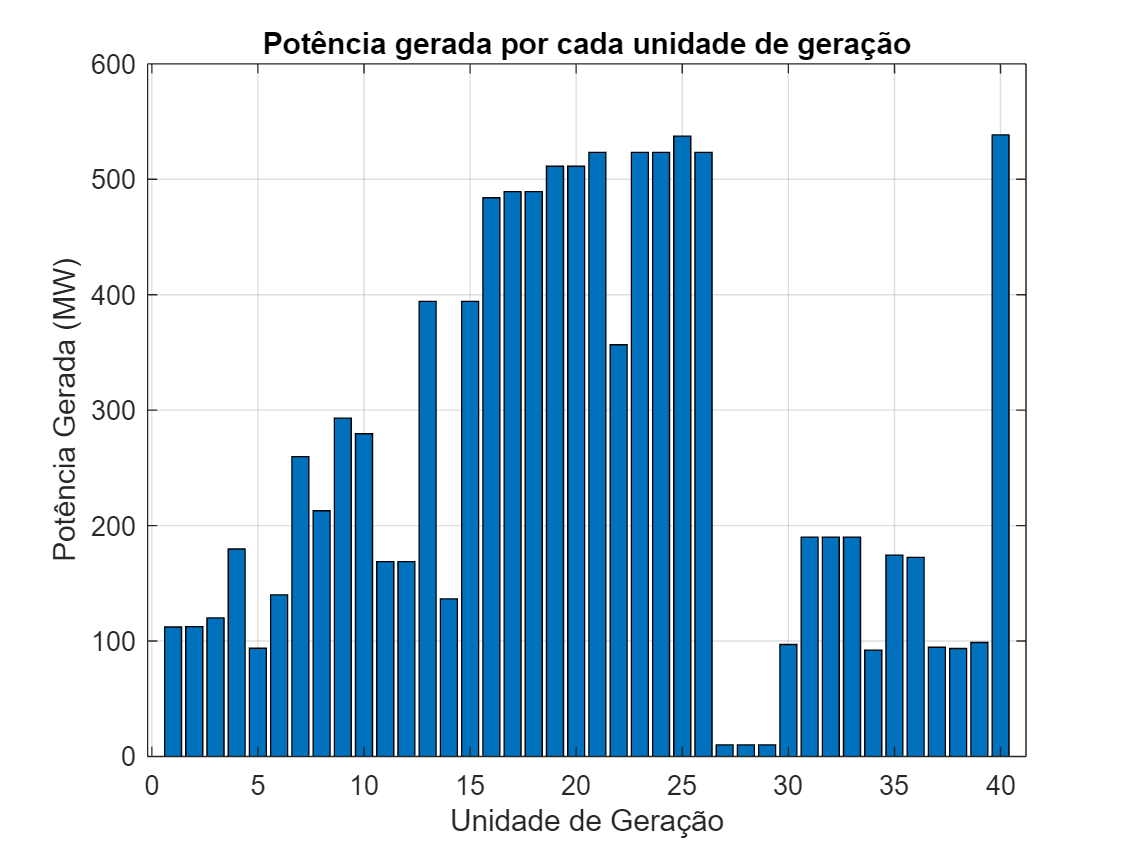


% Gráfico de barras
bar(G, x_best);
xlabel('Unidade de Geração');
ylabel('Potência Gerada (MW)');
title('Potência gerada por cada unidade de geração');
grid on;


total_power_generated = sum(x_best);
fprintf('Potência total gerada: %.5f MW\n', total_power_generated);

Potência total gerada: 10500.00000 MW


fprintf('Custo da produção ($): %.5f ', best_fitness);

Custo da produção ($): 124527.22878 

disp('Melhor solução encontrada:');

Melhor solução encontrada:


disp(x_best);

   1.0e+02 *

   1.121548127176331   1.125304702519193   1.199980173253138   1.797101528429548   0.937372274517855   1.399976868795328   2.598036763033333   2.128262879676774   2.930503763333554   2.796003471650660   1.688244787930878   1.688099916247523   3.942825309547304   1.365546324040860   3.942751482754697   4.840452079735582   4.892979606026763   4.892829812127107   5.112876571791979   5.113291206143930   5.232885901787491   3.566595737026983   5.233012301849856   5.232812296417880   5.373966408136617   5.232738167232948   0.100174097515229   0.100125580706159   0.100387640794630   0.969983973379620   1.899719266050273   1.899968607650802   1.899735210443292   0.921662000729489   1.744023340377198   1.725026342010546   0.945977083601192   0.935605941576043   0.987404766049422   5.384207687931978



toc

Elapsed time is 8.287368 seconds.


### Função de custo de produção da unidade de geração termelétrica

function C = unit_cost(PG_k, a_k, b_k, c_k, e_k, f_k, Pmin_G_k)
    C = a_k * PG_k^2 + b_k * PG_k + c_k + abs(e_k * sin(f_k * (Pmin_G_k - PG_k)));
end
